# Maximum temperature vs. SAR

## Parameters of breast found in literature

One seed, seeds at 5 mm distance and 10 mm distance

% Goal: 
% make small geometry and perform solvepde for different SAR values and
% calculate maximum T. at centre seed and at 5 mm and 10 mm distance. 

runData.runType = 'time';
runData.oneGroup = true;
runData.adjointFlag = false; % --> ???
runData.checkGeometry = true;
runData.plotSolution = true;
runData.hmax = 0.05;          % mesh size: default hmax = 0.05
% Cross section settings
runData.dataset = 'Temp_driven';  
runData.group = 1;          % --> delete: group number to use for the cross-sections, must be one in this case, since only one type/group/NP (nGroups is also 1)

% Load material properties and sources
[modelData.Heat,modelData.Heat_info] = h4_heat_EK(runData.dataset);
% Material assignment to model domains
modelData.materialIDs = 2; % define differently if different material per face (# faces = 3, so 3 elements)

% Source assignment to model domains
modelData.sourceIDs = 2; % define differently if different source term (more heat /concentration)
modelData.fixedSource = 5.0*10^(-3)*60; % Source terms, is equal to metabolic heat for each subdomain. Change if different source terms. 


## Create model, geometry and mesh

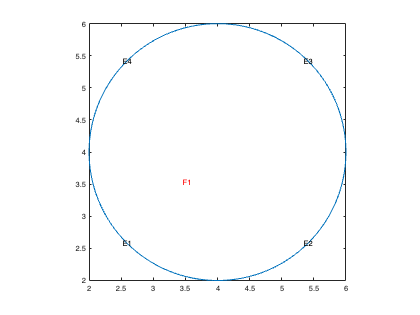

% Create PDE model
[model,modelData] = s1_createPDEModel(runData,modelData);
% Load test geometry
[model,~,centretumor,diametertumor] = r2_createGeometry2D(model,runData);

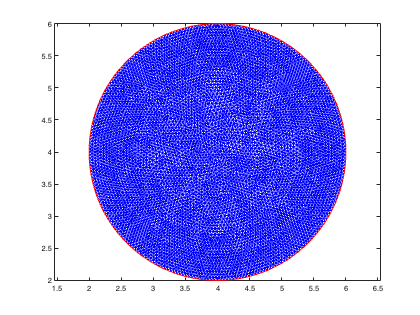

% Generate mesh
[model] = s3_createMesh2D(model,runData);

## Set BC, IC and time scale

nRows = 6

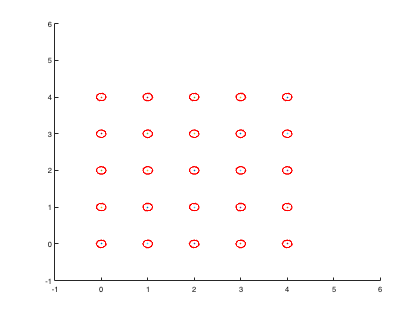

% Boundary conditions:      only applicable for outer boundaries (no information on volume outside control volume)
runData.nBCs.neumann = 1;   % necessary to define if multiple neumann boundaries with different values
runData.BCs.neumann(1) = struct('edge',1:4,'q',0,'g',0); % flux breast [#NPs/m2*s] % must depend on conc. present to not become negative. Which BC?
%runData.BCs.neumann(2) = struct('edge',[2 3],'q',0,'g',0); %6 flux tumor [#NPs/m2*s]
runData.nBCs.dirichlet = 1;
runData.BCs.dirichlet(1) = struct('edge',[],'u',(273.15+37));     % [] means isempty

% Initial conditions
[modelData.x0, modelData.y0, noSeeds] = t4_3_XZ_seedlocationssquare(diametertumor,centretumor);


runData.nICs = 1;                  % necessary to define if multiple initial conditions different per face
modelData.Tinit = 310.15;     % temperature breast tissue
runData.IC(1) = struct('u',modelData.Tinit,'Face',1);   % initial temperature in body and tumour
m = 20; % number of minutes % default total time  = 20 min
runData.timePoints = 0:0.1:m;  % timestep

[model] = s4_2_loadBCIC(model,modelData,runData);

## Solve system of PDE 

date = datestr(now, 'HH:MM')

date = '15:44'

%%% 1 %%%
modelData.seedheat = 1*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results1] = h5_NPHeat2D(model,modelData,runData);
results1 = results1.NodalSolution - 273.15;
solMax1 = max(max(results1))

solMax1 = 38.1849


%%% 2 %%%
modelData.seedheat = 2*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results2] = h5_NPHeat2D(model,modelData,runData);
results2 = results2.NodalSolution - 273.15;
solMax2 = max(max(results2))

solMax2 = 39.3699


%%% 3 %%%
modelData.seedheat = 3*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results3] = h5_NPHeat2D(model,modelData,runData);
results3 = results3.NodalSolution - 273.15;
solMax3 = max(max(results3))

solMax3 = 40.5548


%%% 4 %%%
modelData.seedheat = 4*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results4] = h5_NPHeat2D(model,modelData,runData);
results4 = results4.NodalSolution - 273.15;
solMax4 = max(max(results4))

solMax4 = 41.7405



%%% 5 %%%
modelData.seedheat = 5*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results5] = h5_NPHeat2D(model,modelData,runData);
results5 = results5.NodalSolution - 273.15;
solMax5 = max(max(results5))

solMax5 = 42.9247


%%% 6 %%%
modelData.seedheat = 6*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results6] = h5_NPHeat2D(model,modelData,runData);
results6 = results6.NodalSolution - 273.15;
solMax6 = max(max(results6))

solMax6 = 44.1248


%%% 7 %%%
modelData.seedheat = 7*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results7] = h5_NPHeat2D(model,modelData,runData);
results7 = results7.NodalSolution - 273.15;
solMax7 = max(max(results7))

solMax7 = 45.2945


%%% 8 %%%
modelData.seedheat = 8*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results8] = h5_NPHeat2D(model,modelData,runData);
results8 = results8.NodalSolution - 273.15;
solMax8 = max(max(results8))

solMax8 = 46.4795


%%% 9 %%%
modelData.seedheat = 9*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results9] = h5_NPHeat2D(model,modelData,runData);
results9 = results9.NodalSolution - 273.15;
solMax9 = max(max(results9))

solMax9 = 47.6644


%%% 10 %%%
modelData.seedheat = 10*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results10] = h5_NPHeat2D(model,modelData,runData);
results10 = results10.NodalSolution - 273.15;
solMax10 = max(max(results10))

solMax10 = 48.8493


%%% 11 %%%
modelData.seedheat = 11*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results11] = h5_NPHeat2D(model,modelData,runData);
results11 = results11.NodalSolution - 273.15;
solMax11 = max(max(results11))

solMax11 = 50.0412


%%% 12 %%%
modelData.seedheat = 12*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results12] = h5_NPHeat2D(model,modelData,runData);
results12 = results12.NodalSolution - 273.15;
solMax12 = max(max(results12))

solMax12 = 51.2192


%%% 13 %%%
modelData.seedheat = 13*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results13] = h5_NPHeat2D(model,modelData,runData);
results13 = results13.NodalSolution - 273.15;
solMax13 = max(max(results13))

solMax13 = 52.4042


%%% 14 %%%
modelData.seedheat = 14*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results14] = h5_NPHeat2D(model,modelData,runData);
results14 = results14.NodalSolution - 273.15;
solMax14 = max(max(results14))

solMax14 = 53.5891


%%% 15 %%%
modelData.seedheat = 15*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results15] = h5_NPHeat2D(model,modelData,runData);
results15 = results15.NodalSolution - 273.15;
solMax15 = max(max(results15))

solMax15 = 54.7739


%%% 16 %%%
modelData.seedheat = 16*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results16] = h5_NPHeat2D(model,modelData,runData);
results16 = results16.NodalSolution - 273.15;
solMax16 = max(max(results16))

solMax16 = 55.9589


%%% 17 %%%
modelData.seedheat = 17*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results17] = h5_NPHeat2D(model,modelData,runData);
results17 = results17.NodalSolution - 273.15;
solMax17 = max(max(results17))

solMax17 = 57.1439


%%% 18 %%%
modelData.seedheat = 18*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results18] = h5_NPHeat2D(model,modelData,runData);
results18 = results18.NodalSolution - 273.15;
solMax18 = max(max(results18))

solMax18 = 58.3556


%%% 19 %%%
modelData.seedheat = 19*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results19] = h5_NPHeat2D(model,modelData,runData);
results19 = results19.NodalSolution - 273.15;
solMax19 = max(max(results19))

solMax19 = 59.5220


%%% 20 %%%
modelData.seedheat = 20*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results20] = h5_NPHeat2D(model,modelData,runData);
results20 = results20.NodalSolution - 273.15;
solMax20 = max(max(results20))

solMax20 = 60.6987


%%% 21 %%%
modelData.seedheat = 21*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results21] = h5_NPHeat2D(model,modelData,runData);
results21 = results21.NodalSolution - 273.15;
solMax21 = max(max(results21))

solMax21 = 61.8836


%%% 22 %%%
modelData.seedheat = 22*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results22] = h5_NPHeat2D(model,modelData,runData);
results22 = results22.NodalSolution - 273.15;
solMax22 = max(max(results22))

solMax22 = 63.0879



%%% 23 %%%
modelData.seedheat = 23*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results23] = h5_NPHeat2D(model,modelData,runData);
results23 = results23.NodalSolution - 273.15;
solMax23 = max(max(results23))

solMax23 = 64.2699


%%% 24 %%%
modelData.seedheat = 24*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results24] = h5_NPHeat2D(model,modelData,runData);
results24 = results24.NodalSolution - 273.15;
solMax24 = max(max(results24))

solMax24 = 65.4472


%%% 25 %%%
modelData.seedheat = 25*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results25] = h5_NPHeat2D(model,modelData,runData);
results25 = results25.NodalSolution - 273.15;
solMax25 = max(max(results25))

solMax25 = 66.6232


%%% 26 %%%
modelData.seedheat = 26*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results26] = h5_NPHeat2D(model,modelData,runData);
results26 = results26.NodalSolution - 273.15;
solMax26 = max(max(results26))

solMax26 = 67.8083


%%% 27 %%%
modelData.seedheat = 27*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results27] = h5_NPHeat2D(model,modelData,runData);
results27 = results27.NodalSolution - 273.15;
solMax27 = max(max(results27))

solMax27 = 68.9931


%%% 28 %%%
modelData.seedheat = 28*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results28] = h5_NPHeat2D(model,modelData,runData);
results28 = results28.NodalSolution - 273.15;
solMax28 = max(max(results28))

solMax28 = 70.1782


%%% 29 %%%
modelData.seedheat = 29*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results29] = h5_NPHeat2D(model,modelData,runData);
results29 = results29.NodalSolution - 273.15;
solMax29 = max(max(results29))

solMax29 = 71.3631


%%% 30 %%%
modelData.seedheat = 30*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results30] = h5_NPHeat2D(model,modelData,runData);
results30 = results30.NodalSolution - 273.15;
solMax30 = max(max(results30))

solMax30 = 72.5480


%%% 31 %%%
modelData.seedheat = 31*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results31] = h5_NPHeat2D(model,modelData,runData);
results31 = results31.NodalSolution - 273.15;
solMax31 = max(max(results31))

solMax31 = 73.7330


%%% 32 %%%
modelData.seedheat = 32*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results32] = h5_NPHeat2D(model,modelData,runData);
results32 = results32.NodalSolution - 273.15;
solMax32 = max(max(results32))

solMax32 = 74.9180


%%% 33 %%%
modelData.seedheat = 33*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results33] = h5_NPHeat2D(model,modelData,runData);
results33 = results33.NodalSolution - 273.15;
solMax33 = max(max(results33))

solMax33 = 76.1029



%%% 34 %%%
modelData.seedheat = 34*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results34] = h5_NPHeat2D(model,modelData,runData);
results34 = results34.NodalSolution - 273.15;
solMax34 = max(max(results34))

solMax34 = 77.2879


%%% 35 %%%
modelData.seedheat = 35*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results35] = h5_NPHeat2D(model,modelData,runData);
results35 = results35.NodalSolution - 273.15;
solMax35 = max(max(results35))

solMax35 = 78.4728



%%% 36 %%%
modelData.seedheat = 36*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results36] = h5_NPHeat2D(model,modelData,runData);
results36 = results36.NodalSolution - 273.15;
solMax36 = max(max(results36))

solMax36 = 79.6894



%%% 37 %%%
modelData.seedheat = 37*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results37] = h5_NPHeat2D(model,modelData,runData);
results37 = results37.NodalSolution - 273.15;
solMax37 = max(max(results37))

solMax37 = 80.8606


%%% 38 %%%
modelData.seedheat = 38*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results38] = h5_NPHeat2D(model,modelData,runData);
results38 = results38.NodalSolution - 273.15;
solMax38 = max(max(results38))

solMax38 = 82.0413


%%% 39 %%%
modelData.seedheat = 39*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results39] = h5_NPHeat2D(model,modelData,runData);
results39 = results39.NodalSolution - 273.15;
solMax39 = max(max(results39))

solMax39 = 83.2287


%%% 40 %%%
modelData.seedheat = 40*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
% Solve PDE model
[~,results40] = h5_NPHeat2D(model,modelData,runData);
results40 = results40.NodalSolution - 273.15;
solMax40 = max(max(results40))

solMax40 = 84.4027

## Results: Temperature spread over time

maxT = [solMax1;
    solMax2;
    solMax3;
    solMax4;
    solMax5;
    solMax6;
    solMax7;
    solMax8;
    solMax9;
    solMax10;
    solMax11;
    solMax12;
    solMax13;
    solMax14;
    solMax15;
    solMax16;
    solMax17;
    solMax18;
    solMax19;
    solMax20;
    solMax21;
    solMax22;
    solMax23;
    solMax24;
    solMax25;
    solMax26;
    solMax27;
    solMax28;
    solMax29;
    solMax30;
    solMax31;
    solMax32;
    solMax33;
    solMax34;
    solMax35;
    solMax36;
    solMax37;
    solMax38;
    solMax39;
    solMax40]'

maxT =    38.1849   39.3699   40.5548   41.7405   42.9247   44.1248   45.2945   46.4795   47.6644   48.8493   50.0412   51.2192   52.4042   53.5891   54.7739   55.9589   57.1439   58.3556   59.5220   60.6987   61.8836   63.0879   64.2699   65.4472   66.6232   67.8083   68.9931   70.1782   71.3631   72.5480   73.7330   74.9180   76.1029   77.2879   78.4728   79.6894   80.8606   82.0413   83.2287   84.4027


SAR = linspace(1,40,40)

SAR =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40


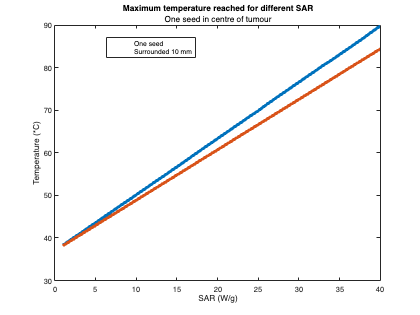

figure
plot(SAR,maxT_oneseed,'LineWidth',4)
hold on
plot(SAR,maxT,'LineWidth',4)
title('Maximum temperature reached for different SAR')
txt = {'One seed in centre of tumour'};
subtitle(txt)
ylabel("Temperature (*C)")
xlabel("SAR (W/g)")
legend('One seed','Surrounded 10 mm')